# Image Processing Fundamentals - Option A: Compare Denoising Filters

Md Mohiuddin Mollah - Digital Signal Processing 2026

**Question:** Which of three filters restores a noisy copy of `rice.png` best, measured with PSNR and SSIM against the original image and checked by eye in a zoomed region?

**Data:** `rice.png` is a MATLAB sample image from the Image Processing Toolbox (256 x 256 pixels, 8-bit grayscale). It shows bright rice grains on a dark background that is brighter at the top than at the bottom. No other image is used.

## 1. Reference image and degraded image

The reference image is degraded exactly as given in the assignment: Gaussian noise (mean 0, variance 0.01) and then salt & pepper noise (density 0.02). The random seed is fixed, so the result is the same on every run.

Iref = imread('rice.png');
rng(42);
Id = imnoise(imnoise(Iref,'gaussian',0,0.01),'salt & pepper',0.02);
fprintf('Image size: %d x %d pixels, class %s\n', size(Iref,1), size(Iref,2), class(Iref));

Image size: 256 x 256 pixels, class uint8


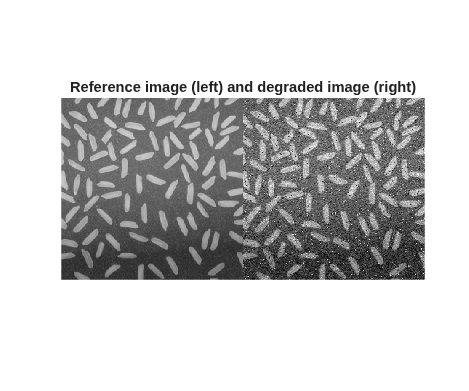

figure;
montage({Iref, Id});
title('Reference image (left) and degraded image (right)');

## 2. Apply the three filters

All three filters use the same degraded image `Id`. No other setting is changed.

Imed  = medfilt2(Id, [3 3]);                     % 3x3 median filter
Igau  = imgaussfilt(Id, 1.5);                    % Gaussian filter, sigma 1.5
Icomb = imgaussfilt(medfilt2(Id, [3 3]), 1);     % 3x3 median, then Gaussian sigma 1

## 3. PSNR and SSIM against the reference

PSNR measures the pixel-by-pixel error in dB (higher is better). SSIM compares local structure, contrast and brightness (1 means identical to the reference).

names = {'Degraded (no filter)'; 'Median 3x3'; 'Gaussian sigma 1.5'; 'Median 3x3 + Gaussian sigma 1'};
imgs = {Id, Imed, Igau, Icomb};
PSNR_dB = zeros(4,1);
SSIM = zeros(4,1);
for k = 1:4
    PSNR_dB(k) = psnr(imgs{k}, Iref);
    SSIM(k) = ssim(imgs{k}, Iref);
end
T = table(names, round(PSNR_dB,2), round(SSIM,4), 'VariableNames', {'Image', 'PSNR_dB', 'SSIM'});
disp(T);

                  Image                  PSNR_dB     SSIM 
    _________________________________    _______    ______

    {'Degraded (no filter)'         }     18.09     0.3696
    {'Median 3x3'                   }     25.37     0.6232
    {'Gaussian sigma 1.5'           }     25.75     0.6921
    {'Median 3x3 + Gaussian sigma 1'}     26.37     0.7051



## 4. Full images

Top row: degraded image and 3x3 median filter. Bottom row: Gaussian filter (sigma 1.5) and median filter followed by Gaussian filter (sigma 1).

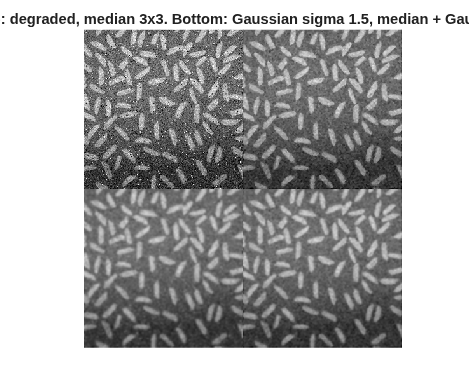

if ~isfolder('results'), mkdir('results'); end
fFull = figure;
montage({Id, Imed, Igau, Icomb}, 'Size', [2 2]);
title('Top: degraded, median 3x3. Bottom: Gaussian sigma 1.5, median + Gaussian');
exportgraphics(fFull, 'results/comparison_full.png', 'Resolution', 200);

## 5. Zoomed region (80 x 80 pixels)

The same region (rows 101 to 180, columns 61 to 140) is cut from every image, so the details can be compared.

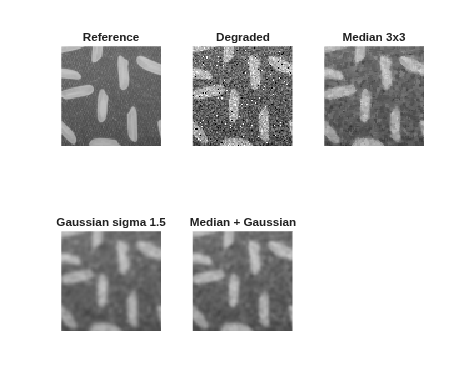

rows = 101:180;
cols = 61:140;
zoomSet = {Iref(rows,cols), Id(rows,cols), Imed(rows,cols), Igau(rows,cols), Icomb(rows,cols)};
zoomNames = {'Reference', 'Degraded', 'Median 3x3', 'Gaussian sigma 1.5', 'Median + Gaussian'};
fZoom = figure;
for k = 1:5
    subplot(2,3,k);
    imshow(zoomSet{k}, 'InitialMagnification', 'fit');
    title(zoomNames{k});
end
exportgraphics(fZoom, 'results/comparison_zoom.png', 'Resolution', 200);

## 6. Save the processed images and the table

The three processed images and the result table are saved in the `results` folder, next to the two comparison figures.

imwrite(Imed,  'results/median_3x3.png');
imwrite(Igau,  'results/gaussian_sigma1_5.png');
imwrite(Icomb, 'results/median_then_gaussian.png');
writetable(T, 'results/metrics.csv');

## 7. Interpretation

**Numbers.** The degraded image has a PSNR of 18.09 dB and an SSIM of 0.37. All three filters improve it clearly. The 3x3 median filter reaches 25.37 dB and 0.62, the Gaussian filter with sigma 1.5 reaches 25.75 dB and 0.69, and the median filter followed by a Gaussian filter with sigma 1 reaches 26.37 dB and 0.71. The combined filter is the best in both measures.

**Zoomed region.** The median filter removes the white and black salt & pepper pixels completely and keeps the edges of the grains sharp. The Gaussian noise is still there: the background looks grainy and patchy. The Gaussian filter gives the smoothest background, but the grain edges are clearly blurred and the grains look wider and softer than in the reference. It does not remove the salt & pepper pixels. It only spreads each one over its neighbours, which leaves faint light and dark spots. The combined filter has no impulse pixels, a smoother background than the median filter alone and sharper grain edges than the Gaussian filter with sigma 1.5.

**Preferred filter.** For this image I prefer the median filter followed by the Gaussian filter. Each step handles the noise type it is suited for: the median filter removes the impulses, and a smaller Gaussian (sigma 1) is then enough for the remaining Gaussian noise, so less blur is needed. The remaining problems are a light blur on the grain edges and a little low-frequency mottling in the background. The fine texture of the background in the reference image is lost with all three filters.

## 8. Limitation

The comparison uses one image, one noise realisation (seed 42) and one fixed setting per filter, so the ranking is only valid for this case. The differences are small (1 dB in PSNR between the best and the worst filter), and another sigma, window size or noise level could change the order. PSNR and SSIM are also averages over the whole image. They do not show where the error is, for example that the Gaussian filter loses edge sharpness while the median filter leaves grain in the background, so the zoomed region is needed next to the numbers.